#### Exportar traza a fichero binario, despues desde una consola bash se genera un fichero .h para C con un comando

clear all
close all
load("CPDAS.mat");

x = trace(1, :);            % una fila = una traza. Datos complejos precision doble
rtrace = single(real(x)); %  Double real -> Single real
itrace = single(imag(x)); %  Double img  -> Single img

% La fft de la NE10 espera los datos así: [Re0 Im0 Re1 Im1 ...] 
data = zeros(1, 2*length(x), 'single');
data(1:2:end) = rtrace; % elementos impares = partes reales
data(2:2:end) = itrace; % elementos pares   = partes imgarias

% Guardar como archivo binario little endian (LSB en addr mas bajo) fid = fopen('cpdas_trace1.bin', 'wb'); fwrite(fid, data, 'single'); fclose(fid);

info = dir('cpdas_trace1.bin');
info.bytes        % tamaño en bytes
length(data)*4    % single = 4 bytes por cada elemento del array (debería coincidir)
clear all
close all

#### Gráfico de trazas 1 y 2 y su resta

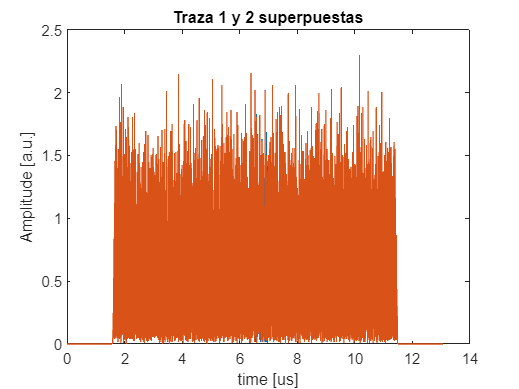

clear all
close all
load("CPDAS.mat");
trace_1 = trace(1,:);
trace_2   = trace(2,:);

figure,plot(t_tr/1e-6,abs(([trace_1;trace_2]))),
xlabel ('time [us]')
ylabel ('Amplitude [a.u.]')
title("Traza 1 y 2 superpuestas")

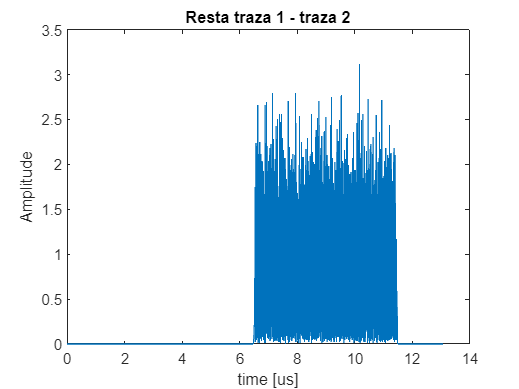


rest = half((trace_1)-(trace_2));

figure
plot(t_tr/1e-6,abs(rest))
xlabel ('time [us]')
ylabel ('Amplitude')
title("Resta traza 1 - traza 2")

N  = length(trace_1) % 130.767

N = 130767

fs = 1/(t_tr(1,2) - t_tr(1,1)) % frecuencia de muestreo 10GHz

fs = 1.0000e+10

fres = fs/N;
freq_axi = linspace(0,fs-fres,N);

FFT de la resta

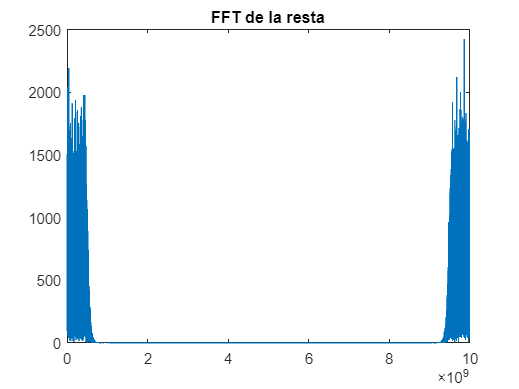

fft_trace1 = fft(trace_1);
plot(freq_axi,abs(fft_trace1))
title("FFT de la resta")

L = 1e3; % 1km fiber
% Queremos ventanas del tamaño del ancho del pulso (100ns = 10m)
% Si muestreamos a 10 Ghz (10e9 muestras por segundo) convertimos
% multiplicando por 100ns y diviendo por 1s:

#### Trazas 1 y 2 divididas en ventanas de 2000 muestras, FFT con padding y convolucion

window = fs * 100e-9;  % 1000 muestras
Npad = 2 * window;     % padding para evitar circularidad
g = 70

g = 70

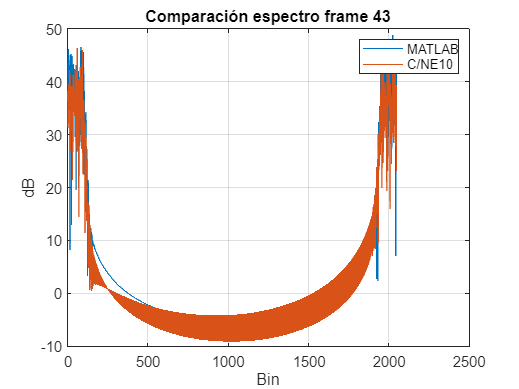


% Particionado sin FFT todavía
trace_1_sliced = buffer(trace_1, window);
trace_2_sliced = buffer(trace_2, window);
num_win = size(trace_1_sliced, 2);

retardos = zeros(1, num_win);

for i = 1:num_win
    ref_win = trace_1_sliced(:, i);
    test_win = trace_2_sliced(:, i);

    % Zero-padding para correlación lineal
    ref_win_padded = [ref_win; zeros(window, 1)];
    test_win_padded = [test_win; zeros(window, 1)];

    % Correlación cruzada por FFT con padding
    corr_fft = ifft(fft(ref_win_padded) .* conj(fft(test_win_padded)));
    corr_fft = fftshift(corr_fft);
    corr_fft = corr_fft/max(abs(corr_fft));
    % Vector de lags
    lags = -(window):window-1;

    % Buscar el lag que maximiza la correlación
    [~, max_idx] = max(abs(corr_fft));
    lag = lags(max_idx);  % retardo en muestras
    if i == g
        plot(lags, abs(corr_fft))
    end
    retardos(i) = lag;
end

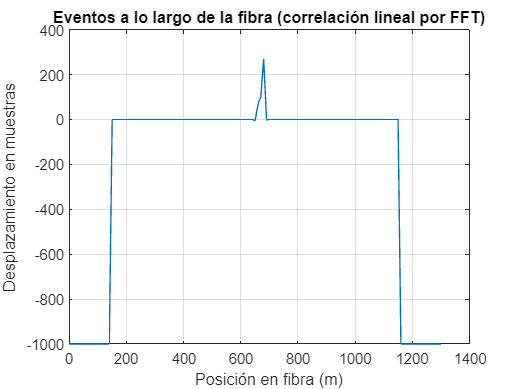


% Eje de posición espacial
location = (0:num_win-1) * (window * 0.01);  % cada ventana cubre 10 m

% Gráfico
figure;
plot(location, retardos);
xlabel('Posición en fibra (m)');
ylabel('Desplazamiento en muestras');
title('Eventos a lo largo de la fibra (correlación lineal por FFT)');
grid on;

#### Trazas 1 y 2 divididas en ventanas de 2000 muestras, FFT sin padding y convolucion

window = fs*100e-9 % 10e9 Hz * 100e-9 s = 1000 muestras

window = 1000

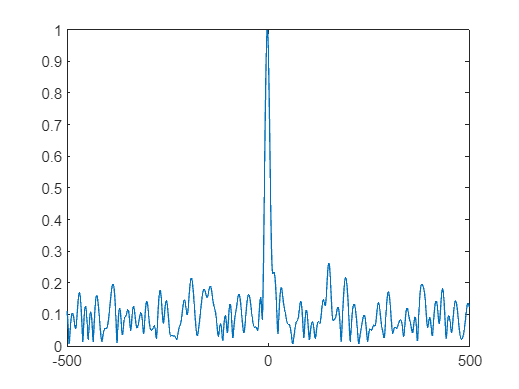

trace_1_sliced = fft(buffer(trace_1, window));
trace_2_sliced = fft(buffer(trace_2, window));
num_win = size(trace_1_sliced,2);

for i=1:num_win
    ref_win = trace_1_sliced(:,i);
    test_win = trace_2_sliced(:,i);
    
    corr_fft = ifft(ref_win .* conj(test_win));  % correlación cruzada
    
    % fftshift para centrar el espectro en 0 y no ver las réplicas, solo
    % los tonos reales.
    corr_shifted = fftshift(corr_fft);
    corr_shifted = corr_shifted/max(abs(corr_shifted));
    % Vector de lags, como la correlación se calcula como el producto en
    % frecuenia el tamaño resultante es igual al de entrada. Entonces los
    % lags van desde -windows/2 hasta windows/2
    lags = -window/2:window/2-1;
    if i == g % dar un valor a g entre 1 y num_win para plotear una ventana concreta
        plot(lags, abs(corr_shifted))
    end
    % Buscar el lag que maximiza la correlación
    [~, max_idx] = max(abs(corr_shifted));
    retardos(i) = lags(max_idx); % retardo en muestras
end

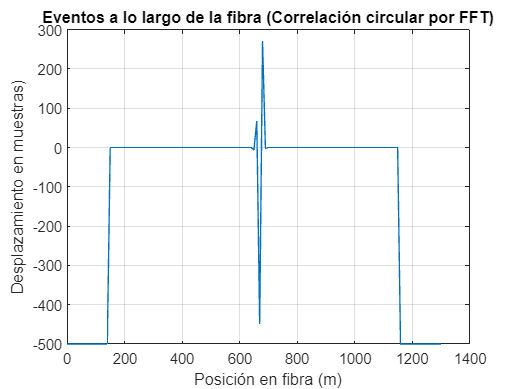


location = (0:num_win-1) * (window * 0.01);  % posición de cada ventana (cada ventana son 1000 muestras de datos separados 10 cm)
figure;
plot(location, retardos);
xlabel('Posición en fibra (m)');
ylabel('Desplazamiento en muestras)');
title('Eventos a lo largo de la fibra (Correlación circular por FFT)');
grid on;

#### Correlación directa con función  de matlab

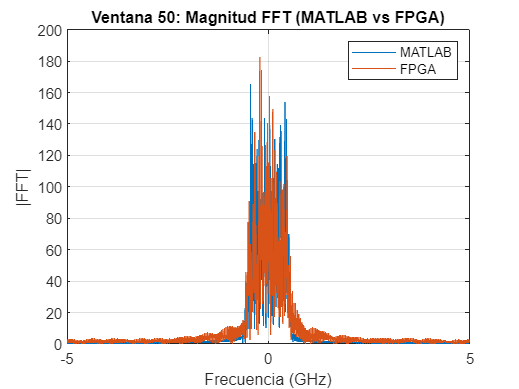

window = fs*100e-9 % 10e9 Hz * 100e-9 s = 1000 muestras
trace_1_sliced = buffer(trace_1, window);
trace_2_sliced = buffer(trace_2, window);
num_win = size(trace_1_sliced,2);

for i=1:num_win
    ref_win = (trace_1_sliced(:,i));
    test_win = (trace_2_sliced(:,i));
    
    [corr_vec, lags] = xcorr(ref_win, test_win,'coeff');  % correlación cruzada
    % Buscar el lag que maximiza la correlación
    [~, max_idx] = max(abs(corr_vec));
    retardos(i) = lags(max_idx); % retardo en muestras
end

location = (0:num_win-1) * (window * 0.01);  % posición de cada ventana (cada ventana son 1000 muestras de datos separados 10 cm)
figure;
plot(location, retardos);
xlabel('Posición en fibra (m)');
ylabel('Desplazamiento en muestras)');
title('Eventos a lo largo de la fibra');
grid on;
